clear all
syms x(t) y(t) theta(t) Fx(t) Fy(t) t m g L
F=[Fx(t);Fy(t)]

$$F = \left(\begin{array}{c} \mathrm{Fx}\left(t\right)\\ \mathrm{Fy}\left(t\right) \end{array}\right)$$

rG=[x(t);y(t)]

$$rG = \left(\begin{array}{c} x\left(t\right)\\ y\left(t\right) \end{array}\right)$$

m=1;
L=2;
g=9.81;
%F=ma
eq1=m*diff(rG,t,2)==(F-m*g*[0;1])

$$eq1 = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\mathrm{Fx}\left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\mathrm{Fy}\left(t\right)-\frac{981}{100} \end{array}\right)$$

%IG theta''=M
eq2=1/12*m*L^2*diff(theta,t,2) ==( -L/2*(Fy(t)*sin(theta(t)))-Fx(t)*cos(theta(t)))

$$eq2(t) = \frac{\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)}{3}=-\cos\left(\theta \left(t\right)\right)\,\mathrm{Fx}\left(t\right)-\sin\left(\theta \left(t\right)\right)\,\mathrm{Fy}\left(t\right)$$

%Keep the thing in place. 
eq3=[x(t)-L/2*sin(theta(t));y+L/2*cos(theta(t))]==[0;0]

$$eq3(t) = \left(\begin{array}{c} x\left(t\right)-\sin\left(\theta \left(t\right)\right)=0\\ \cos\left(\theta \left(t\right)\right)+y\left(t\right)=0 \end{array}\right)$$

Initial Conditions:
Y0/YP0:
x: 0.000000 xt:1.000000
y: -1.000000 yt:0.000000
theta: 0.000000 thetat:1.000000
Fx: 0.000000 Fxt:0.000000
Fy: 10.810000 Fyt:0.000000
Dxt: 1.000000 Dxtt:0.000000
Dyt: 0.000000 Dytt:1.000000
Dthetat: 1.000000 Dthetatt:0.000000


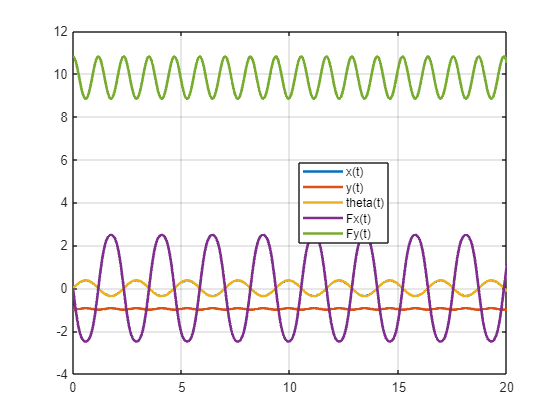

soln=mechanicsAsDAE([eq1;eq2],[eq3],[],[x,y,theta,Fx,Fy],0,20,[x==0,diff(theta)==1]);

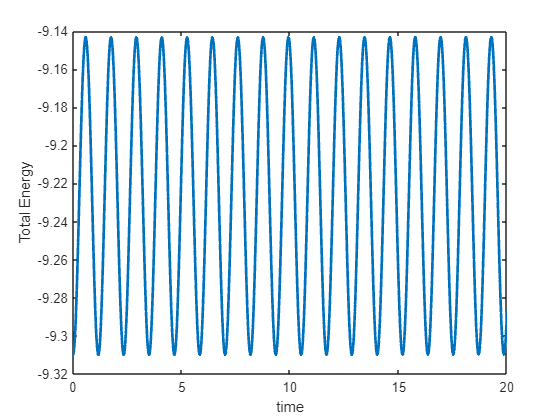

KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2);
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

[DEs,PP] = analyzeSystem([eq1;eq2],eq3,[],[x,y,Fx,Fy,theta],[theta,diff(theta)])

There are 9 equations, and 5 unknown time-varying functions.
The non-algebraic (force) functions are:
x(t)
y(t)
theta(t)

Adding in all constraints, and counting pure symbols (so that x, Dxt, Dxtt count as 3 symbols) I get:
equations: 9
symbols:11
free parameters: 2.

Expected number of state variables: 2



$$DEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{2943\,\sin\left(\theta \left(t\right)\right)}{400}$$

$$PP = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\sigma_{2}\\ \frac{\partial }{\partial t}y\left(t\right)=\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=\sigma_{3}+\sigma_{1}-\frac{2943}{400}\\ \mathrm{Fx}\left(t\right)=\sigma_{2}\\ \mathrm{Fy}\left(t\right)=\sigma_{3}+\sigma_{1}+\frac{981}{400}\\ x\left(t\right)=\sin\left(\theta \left(t\right)\right)\\ y\left(t\right)=-\cos\left(\theta \left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2943\,{\cos\left(\theta \left(t\right)\right)}^{2}}{400}\\ \sigma_{2}=-\sin\left(\theta \left(t\right)\right)\,\sigma_{4}-\frac{2943\,\sin\left(2\,\theta \left(t\right)\right)}{800}\\ \sigma_{3}=\cos\left(\theta \left(t\right)\right)\,\sigma_{4}\\ \sigma_{4}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

soln=timeStepODESystem(DEs,[theta],{theta==0,diff(theta)==1},[0,20],PP)

soln = struct with fields:
          t: [325×1 double]
      theta: [325×1 double]
    Dthetat: [325×1 double]
        Dxt: [325×1 double]
       Dxtt: [325×1 double]
        Dyt: [325×1 double]
       Dytt: [325×1 double]
         Fx: [325×1 double]
         Fy: [325×1 double]
          x: [325×1 double]
          y: [325×1 double]


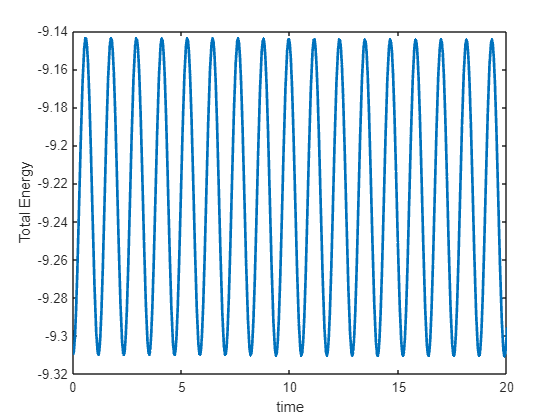

KineticEnergy=1/2*m*(soln.Dxt.^2+soln.Dyt.^2);
PotentialEnergy=m*soln.y*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')